% CV Homework-3 Question 1

videoInputReader = VideoReader('InputVideo.mp4','CurrentTime',1);
totalFrames = videoInputReader.NumFrames;

n=totalFrames;
for k = 1:n
    readFrames = read(videoInputReader,k);
    imwrite(readFrames,['Image' int2str(k), '.jpg']);
    imageloop(k)=image(readFrames);
end




imgA = im2gray(imread('Image1.jpg'));
imgB = im2gray(imread('Image295.jpg'));
currentFrame = imgB;


imshow(currentFrame);
axis on;
set(gcf, 'Position', get(0,'Screensize')); % Maximize figure.    
myRectangle = drawrectangle('Label','PICK YOUR REGION OF INTEREST','Color',[1 1 1]);% this helps us to draw over the frame

RectanglePos = myRectangle.Position();
RectanglePos = round(RectanglePos);

close(gcf)
currentFrame = imcrop(currentFrame,RectanglePos);
imgB = currentFrame

Bag_2 = 448×246 uint8 matrix
   171   171   171   171   171   171   171   171   171   171   171   171   171   170   170   170   170   170   170   170   170   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172
   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   172   172   172   172   172
   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   172   172   172   172   172
   171   171   171   171   171   171   171   171   171   171   171  

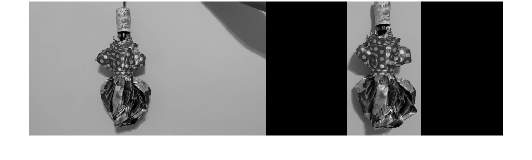


montage({imgA,imgB})

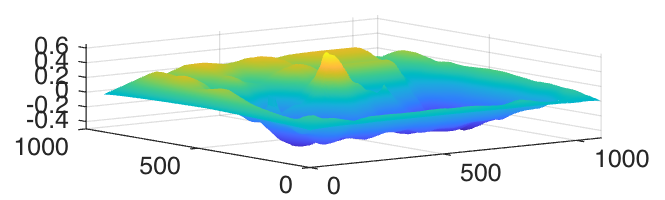


corr = normxcorr2(imgB,imgA);
surf(corr)
shading flat

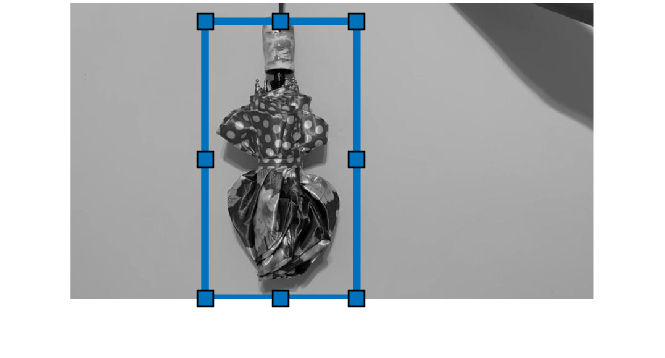


[yeak,xpeak] = find(corr==max(corr(:)));

y_offset = ypeak-size(imgB,1);
x_offset = xpeak-size(imgB,2);

imshow(imgA)
drawrectangle(gca,'Position',[x_offset,y_offset,size(imgB,2),size(imgB,1)], ...
    'FaceAlpha',0);